clc;close all;clear all;

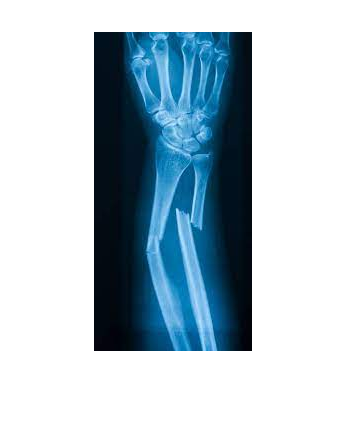

% Read Image

img = imread('images.jpg');
imshow(img);

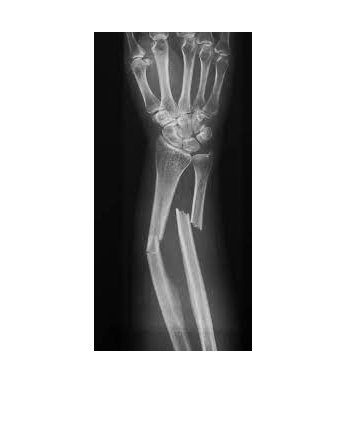

grayimg = rgb2gray(img);imshow(grayimg);

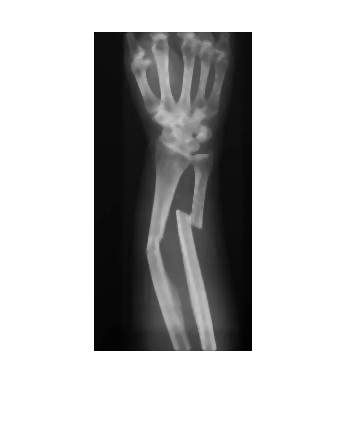

% Did this, don't know why but achha lagta he
grayimg = medfilt2(grayimg,[5 5]);
imshow(grayimg)

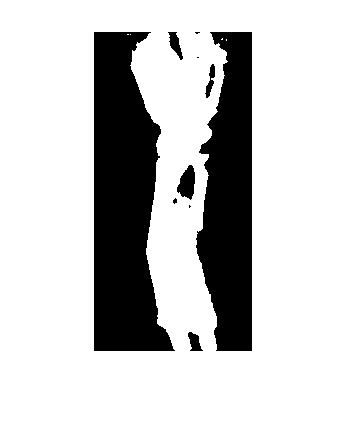

% Convert to Binary
binImg = imbinarize(grayimg,"global");imshow(binImg);

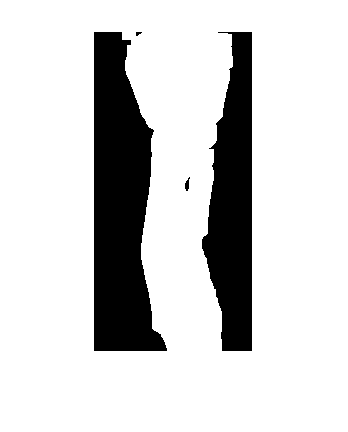

% Dilate in order to fill in cracks and gaps
dilImg = bwmorph(binImg,"dilate",5);imshow(dilImg)

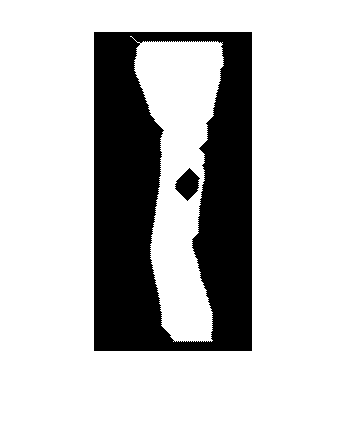

% Shrink order to conserve the structure but reduce the effect of Dilation
shrink = bwmorph(dilImg,"shrink",5);
imshow(shrink);

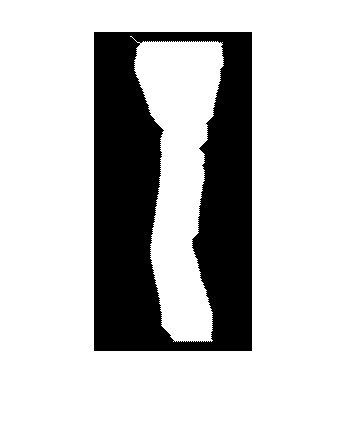

% Fill Holes in the previous results
filled_shrink = imfill(shrink,"holes");
imshow(filled_shrink);

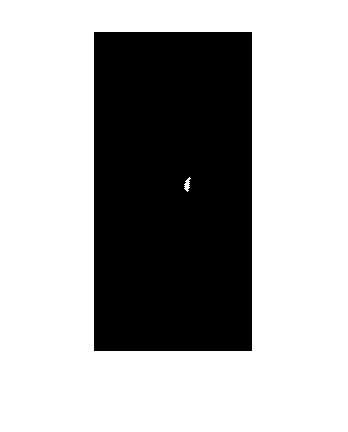

% Find difference which reflects the gap.
crack = xor(filled_shrink,shrink);
crack = bwmorph(crack,'shrink',5);
imshow(crack);

clf;
[r,c] = find(crack == 1);
[r,c]

ans =    153    91
   155    91
   157    91
   150    92
   152    92
   153    92
   154    92
   155    92
   156    92
   157    92


mid_idx = floor(length(r)/2);
mid_point = [r(mid_idx), c(mid_idx)];

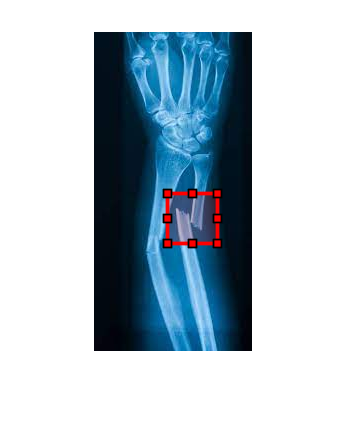

figure(1);
imshow(img);
images.roi.Rectangle(gca,'Position',[mid_point(2)-20,mid_point(1)+10,50,50],'Color','r');